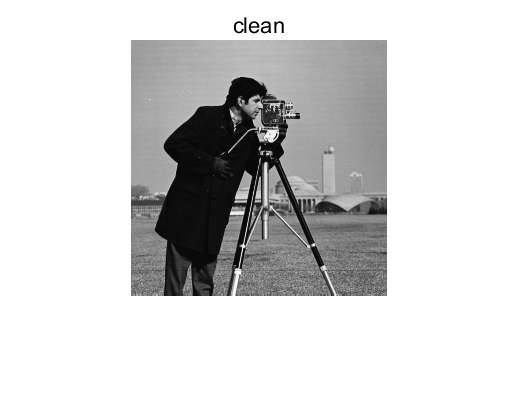

img_clean = double(imread('cameraman.tif')); 
%设定随机数种子，使得实验可重复
rng('default') 
%清晰图像上加入标准差为sigma的高斯噪声得到噪声图像u0~[-78,329]
sigma = 25;
img_noise = img_clean + 25*randn(size(img_clean)); 
%显示清晰图像和噪声
imshow(uint8(img_clean))
title 'clean'

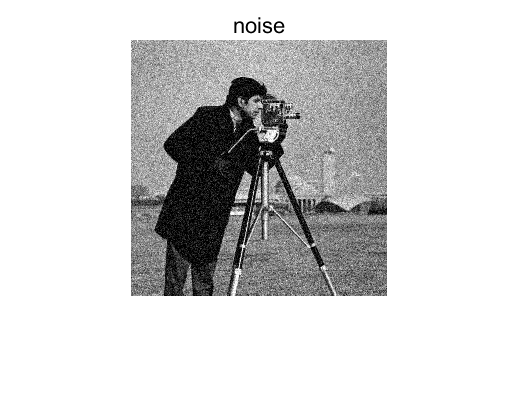


imshow(uint8(img_noise))
title 'noise'

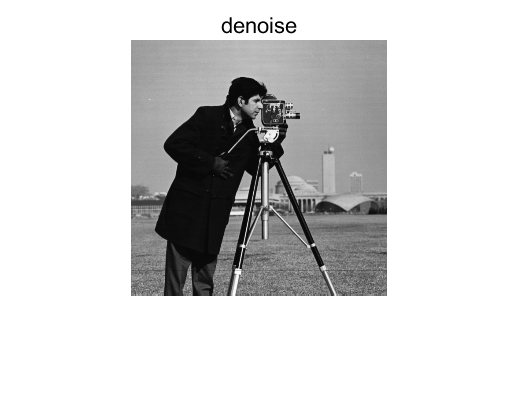

img_denoise = TV_Denoise(img_noise, 0.04, 0.05);
imshow(uint8(img_clean))
title 'denoise'


psnr(uint8(img_denoise), uint8(img_clean))

ans = 27.1910

ssim(uint8(img_denoise), uint8(img_clean))

ans = 0.8029